## Analysis of Simulations

### Trajectorie

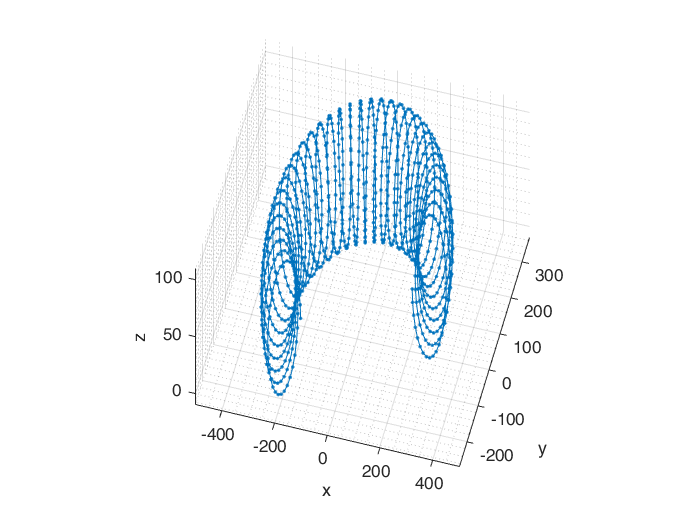

plot3(traj(1,:),traj(2,:),traj(3,:),'Marker','.','LineStyle','-')
xlabel('x');ylabel('y');zlabel('z')
grid on; grid minor;
axis vis3d; view([15 60]);rotate3d on;

### Vergleich Berechnung und Simulation

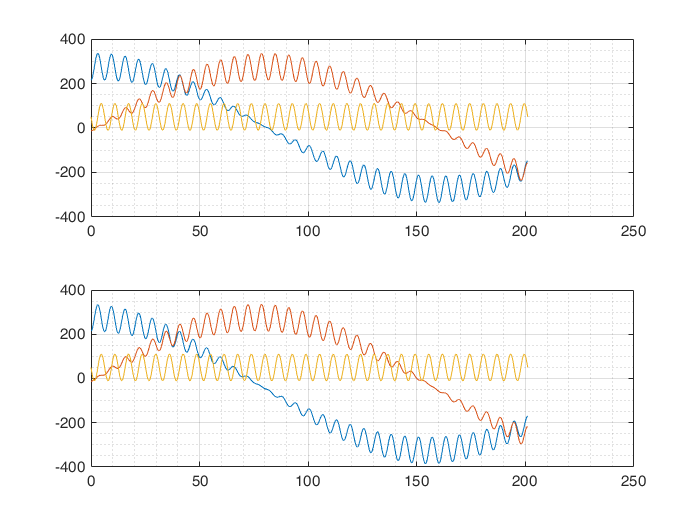

tiledlayout(2,1); nexttile(1);
plot(anaT,traj);
grid on; grid minor;
nexttile(2);
plot(anaT,simCordRS)
grid on; grid minor;

## Vergleich der einzelnen Achsen

### x-Achse

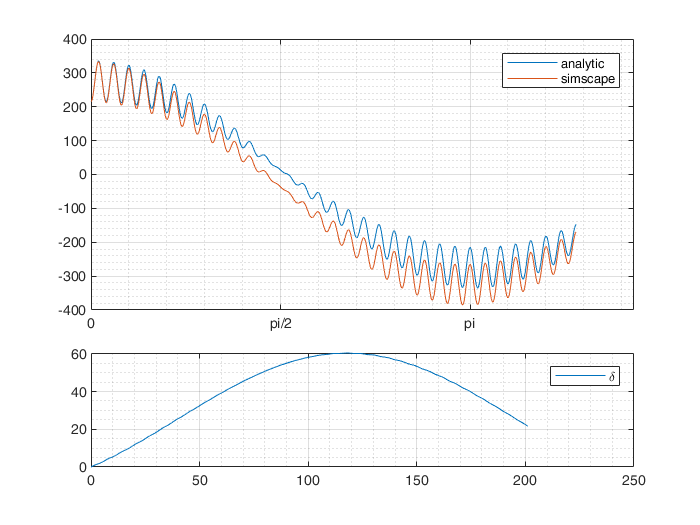

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(simAngRS,[traj(1,:);simCordRS(1,:)])
set(gca,'XTick',0:pi/2:2*pi)
set(gca,'XTickLabel',{'0','pi/2','pi','3*pi/2','2*pi'})

legend('analytic','simscape');
grid on; grid minor;
nexttile(3);
plot(anaT,[traj(1,:)-simCordRS(1,:)])
legend('\delta');
grid on; grid minor;

### y-Achse

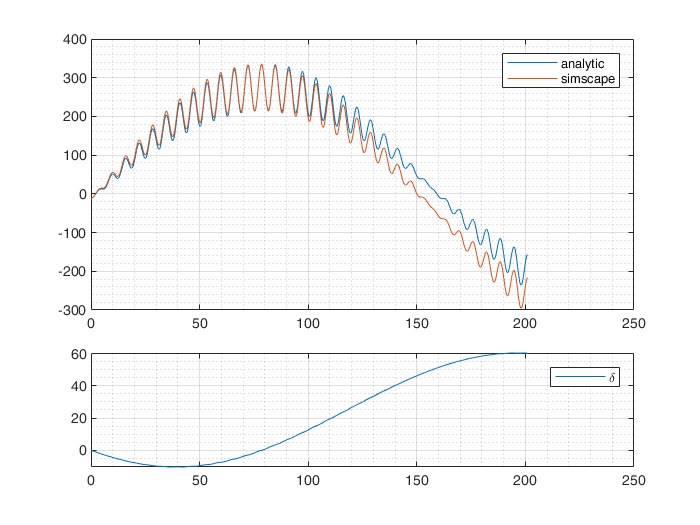

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(anaT,[traj(2,:);simCordRS(2,:)])
legend('analytic','simscape');
grid on; grid minor;
nexttile(3);
plot(anaT,[traj(2,:)-simCordRS(2,:)])
legend('\delta');
grid on; grid minor;

### z-Achse

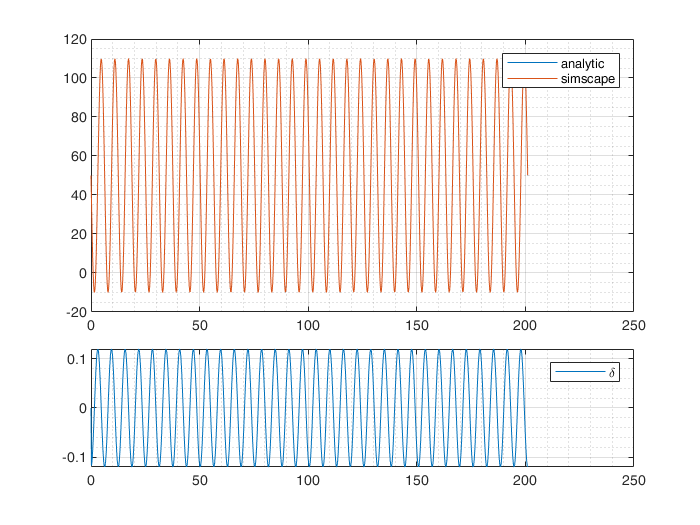

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(anaT,[traj(3,:);simCordRS(3,:)])
legend('analytic','simscape');
grid on; grid minor;
nexttile(3);
plot(anaT,[traj(3,:)-simCordRS(3,:)])
legend('\delta');
grid on; grid minor;